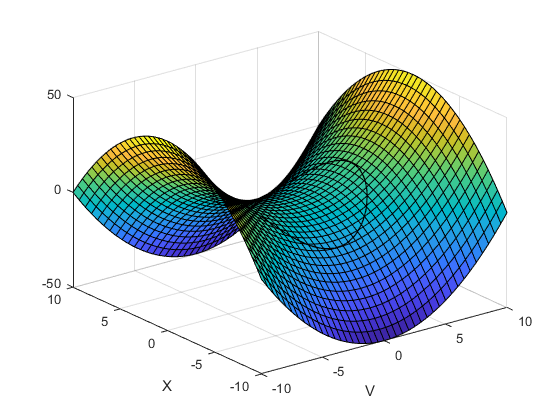

[V,X] = meshgrid(-10:0.5:10, -10:0.5:10);
Z = 1/2*V.^2 - 1/2*X.^2;
surf(V,X,Z)
xlabel('V')
ylabel('X')
hold on


f = @(t,x) [x(2); -x(1)];

[t, ya] = ode45(f,[0,10],[0, 5]);
z = 1/2*ya(:,1).^2 - 1/2*ya(:,2).^2;
plot3(ya(:,1),ya(:,2),z,"Color",'r')

f = @(t,x) [x(2); -x(1)];

[t, ya] = ode45(f,[0,10],[0, 5]);
z = 1/2*ya(:,1).^2 - 1/2*ya(:,2).^2;
plot3(ya(:,1),ya(:,2),z,"Color",'k')
hold off

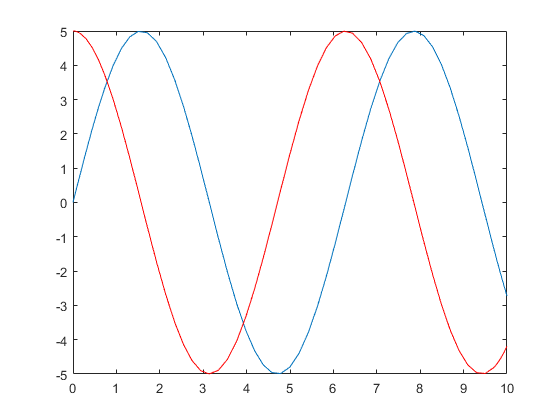

plot(t, ya(:,1))
hold on
plot(t, ya(:,2),'Color','r')
hold off

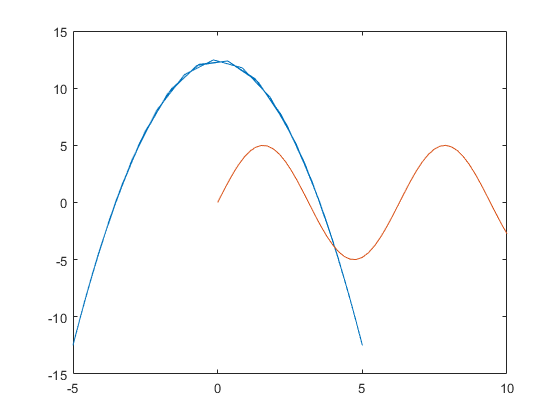

plot(ya(:,2), z)
hold on
plot(t, ya(:,1))
hold off

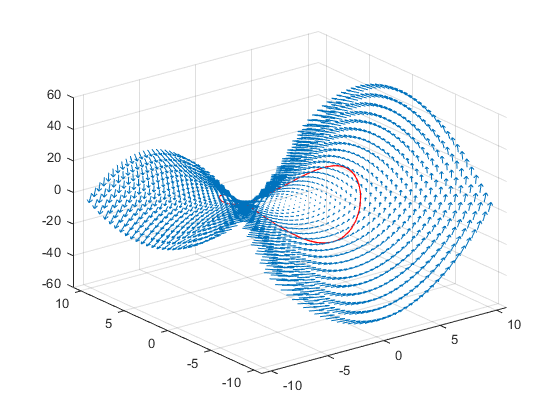

quiver3(V,X,Z,-X,V,-X+V)
hold on
f = @(t,x) [x(2); -x(1)];

[t, ya] = ode45(f,[0,10],[0, 5]);
z = 1/2*ya(:,1).^2 - 1/2*ya(:,2).^2;
plot3(ya(:,1),ya(:,2),z,"Color",'r')

hold off

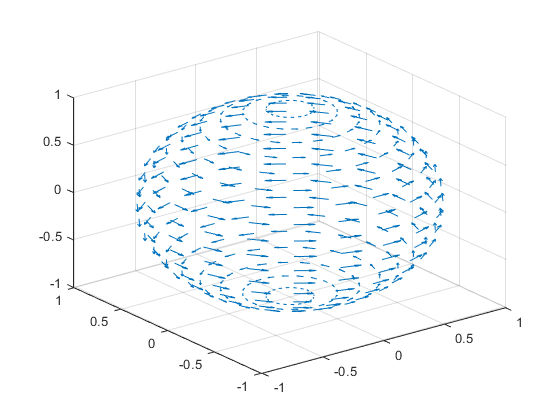

[X,Y,Z]=sphere;
quiver3(X,Y,Z,-Y,X,Z*0)

syms x

G=1;
M=1;

[X Y] = meshgrid(2:0.2:5, -5:0.2:5);
U = Y.^0;
V = (1-2*G*M./X).^(-1);
L = sqrt(U.^2 + V.^2);

quiver(X,Y,U./L,V./L)
hold on
quiver(X,Y,-U./L,V./L)

x = 2:0.1:5;
t = x + 2*log(x./2-1);
t2 = -t

t2 =        Inf    3.8915    2.4052    1.4942    0.8189    0.2726   -0.1921   -0.6004   -0.9674   -1.3030   -1.6137   -1.9043   -2.1783   -2.4384   -2.6867   -2.9246   -3.1537   -3.3750   -3.5893   -3.7974   -4.0000   -4.1976   -4.3906   -4.5795   -4.7646   -4.9463   -5.1247   -5.3002   -5.4729   -5.6431   -5.8109


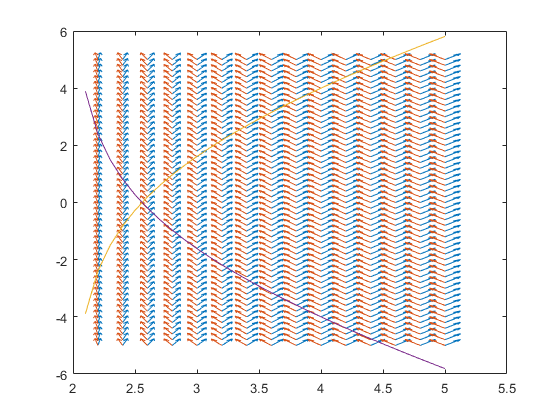


plot(x,t)
plot(x,t2)
hold off

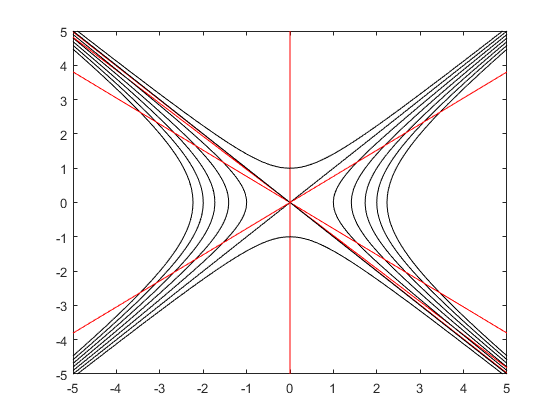

syms x y

for i=-5:1
    fimplicit(y^2-x^2==i, "Color",'k')
    hold on
    fimplicit(y == x*tanh(i), "Color",'r')
end
hold off

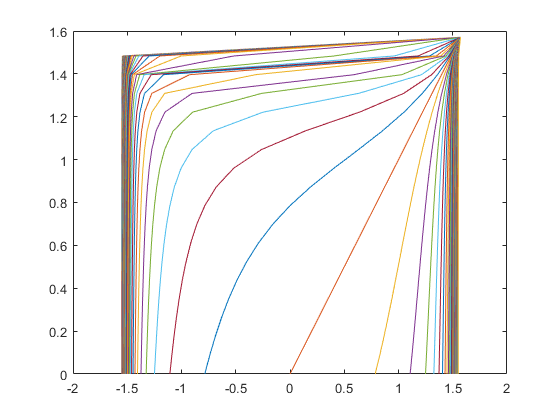

r = 0:pi/36:pi/2;
for c = -50:50
    t = atan(tan(r)+c);
    
    plot(t,r)
    hold on
end
hold off

syms x y
f = x- y^2/2

$$f = x-\frac{y^{2}}{2}$$

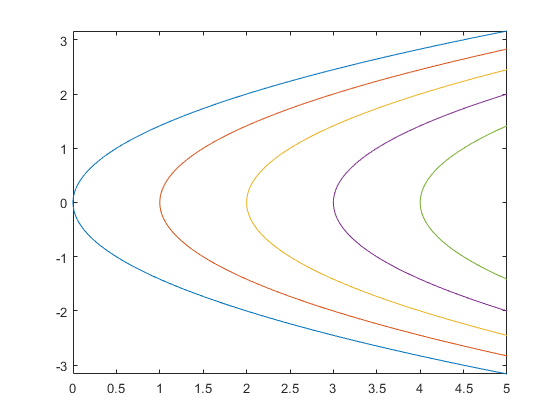

for i = 0:5
fimplicit(f==i)
hold on
end
hold off

syms x y
f = x^2- y^2

$$f = x^{2}-y^{2}$$

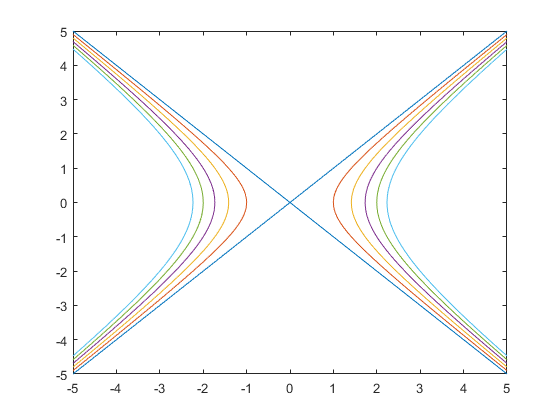

for i = 0:5
fimplicit(f==i)
hold on
end
hold off